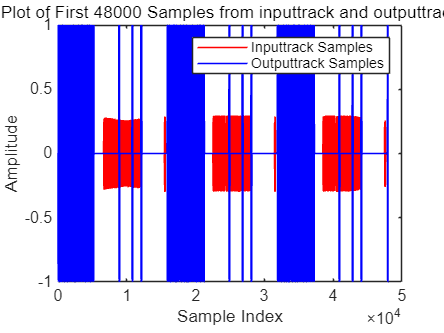

input_data = readmatrix('input_track.csv');
output_data = readmatrix('output_track.csv');

% 提取前 48000 个样本
input_samples = input_data(1:48000);
output_samples = output_data(1:48000);
%计算能量
powers = zeros(1, length(input_samples)); % 初始化存储数组
power = 0; % 初始能量为0
alpha = 1.0 / 64; % 平滑因子
for i = 1:length(input_samples)
    currentSample = input_samples(i);
    power = power * (1 - alpha) + (currentSample^2) * alpha;
    powers(i) = power; % 将当前 power 保存到 powers 数组中
end


% 绘制 inputtrack 的前 48000 个样本（红色）
plot(1:48000, input_samples, 'r');
hold on;

% 绘制 outputtrack 的前 48000 个样本（蓝色）
plot(1:48000, output_samples, 'b');

% 添加图形标签和标题
xlabel('Sample Index');
ylabel('Amplitude');
title('Plot of First 48000 Samples from inputtrack and outputtrack');
legend('Inputtrack Samples', 'Outputtrack Samples');

% 关闭 hold 状态
hold off;

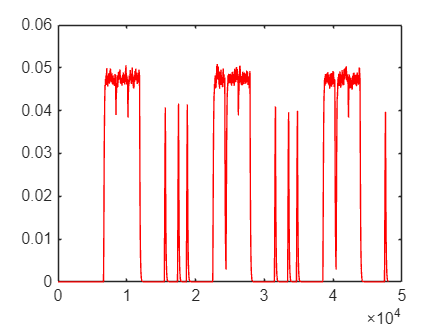


plot(1:48000, powers, 'r');

input_data = readmatrix('input_track.csv');
input_samples = input_data(1+97000:96000+97000);
%计算能量
powers = zeros(1, length(input_samples)); % 初始化存储数组
power = 0; % 初始能量为0
alpha = 1.0 / 24; % 平滑因子
for i = 1:length(input_samples)
    currentSample = input_samples(i);
    power = power * (1 - alpha) + (currentSample^2) * alpha;
    powers(i) = power; % 将当前 power 保存到 powers 数组中
end


% 绘制 inputtrack 的前 48000 个样本（红色）
plot(1:length(input_samples), input_samples, 'r');
hold on;

% 添加图形标签和标题
xlabel('Sample Index');
ylabel('Amplitude');
title('Plot of First 48000 Samples from inputtrack and outputtrack');
legend('Inputtrack Samples', 'Outputtrack Samples');

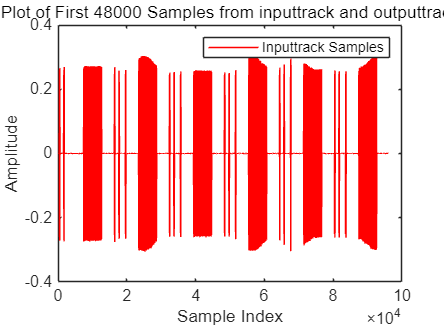


% 关闭 hold 状态
hold off;

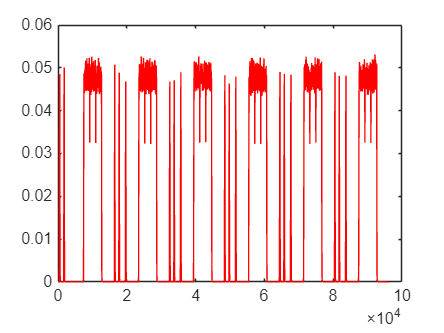


plot(1:length(powers), powers, 'r');